# Parks-McClellan Algorithm

N_1 = 10;
N_2 = 25;
N_3 = 50;
f = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.8 0.9 1];
a = [0 0 1 1 0 0 0.5 0.5 0 0];

set(groot, 'defaultAxesFontSize',15);

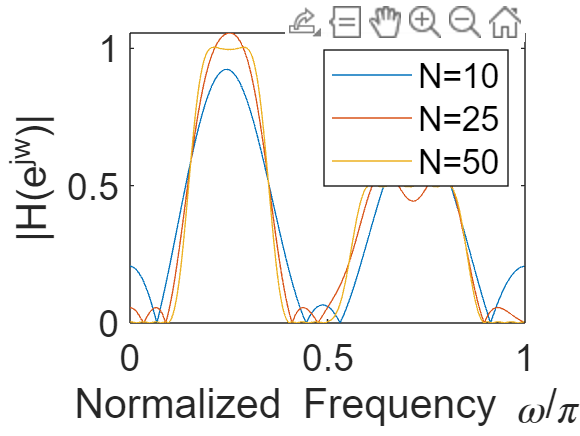

params = firpm(N_1, f, a);
[H_10 w_10] = freqz(params,1,512);
figure;
plot(w_10/pi,abs(H_10))
hold on;

params = firpm(N_2, f, a);
[H_25 w_25] = freqz(params,1,512);
plot(w_25/pi,abs(H_25))
hold on;

params = firpm(N_3, f, a);
[H_50 w_50] = freqz(params,1,512);
plot(w_50/pi,abs(H_50))
hold off;
legend(["N=10", "N=25", "N=50"]);
xlabel("Normalized Frequency \omega/\pi")
ylabel("|H(e^{jw})|")